**DSP Assignment No. 2**

**Name: **Muhammad Abdullah Khalid

**Class: **BEE-10D

**Registeration No. **245369

**Task 1**

Record your voice using audiorecorder function.

re = audiorecorder(44100, 8, 1);
recordblocking(re, 2);  %Recording the audio
stop(re);

**Task 2**

Plot the voice signal in time and frequency domains.

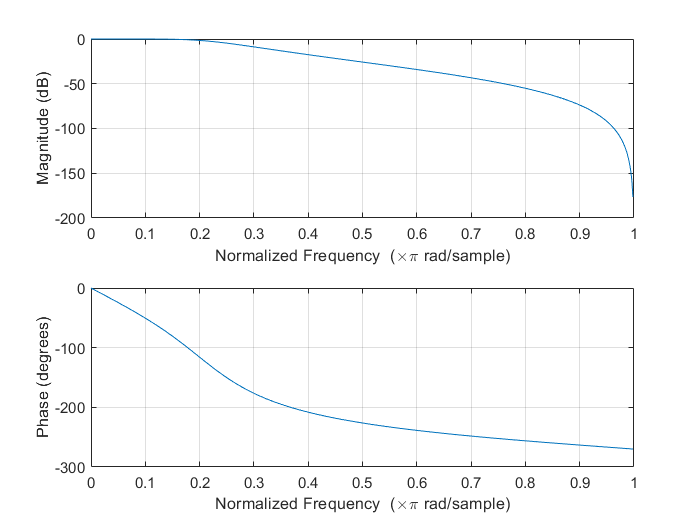

[sound_sample, Fs] = audioread('sound.wav');
t = 0:1/44100:2-1/44100;
sound_sample = sound_sample;
figure(1);
subplot(211);

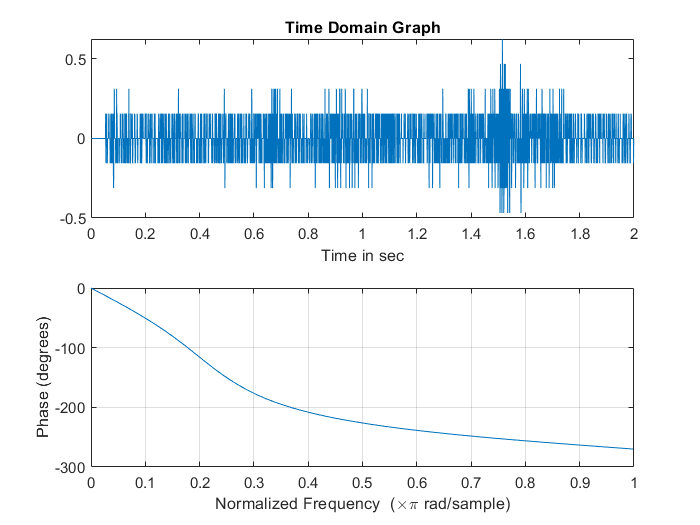

plot(t, sound_sample); %Plotting in Time Domain
title('Time Domain Graph');
xlabel('Time in sec');
Sound = fft(sound_sample, 44100);
subplot(212);

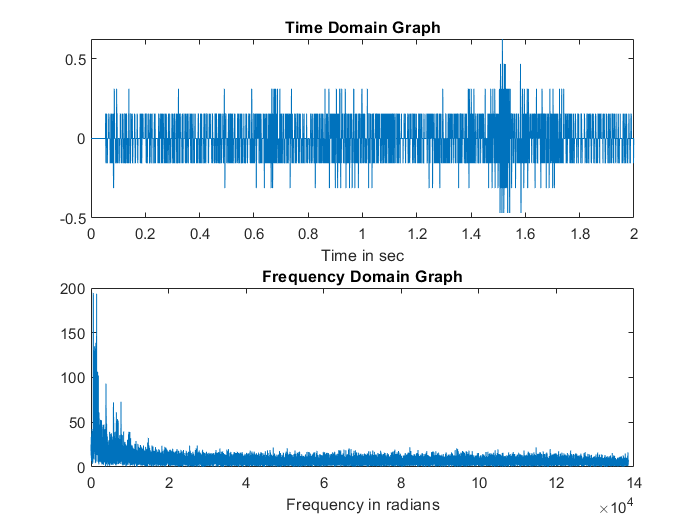

f = 0:2*pi:22050*2*pi-2*pi;
plot(f,abs(Sound(1:22050)));    %Plotting in Frequency Domain
title('Frequency Domain Graph');
xlabel('Frequency in radians');

**Task 3**

Make a filter to filter out frequencies greater than 5kHz.

[b, a] = butter(3, 5000/22050);
filtered_sound = filter(b, a, sound_sample);
Filtered_sound = fft(filtered_sound, 44100);
figure(2);
freqz(b, a);

figure(3);
plot(f/(2*pi), abs(Filtered_sound(1:22050)));   %Plotting the sound after Filtering
title('Frequency Domain Graph of Filtered Sound');
xlabel('Frequency in Hz');
disp('This sort of filter is safe as more useful frequencies are in the 0-5kHz, and other noise is removed.');

This sort of filter is safe as more useful frequencies are in the 0-5kHz, and other noise is removed.


disp('As it can be seen the frequencies above 5Hz have been suppressed');

As it can be seen the frequencies above 5Hz have been suppressed


**Task 4**

Make the signal from continous to discrete, using the zero order hold filter.

First we study the zero order hold filter

del = [1];
del = [del, zeros(1, 88199)];   %Making impulse function
T = 5/44100;
for n = 1:88200 %Appling the Zero-Order Hold filter with Sampling T = 5/44100s to an impulse to get impulse response
    h(n) = del(ceil(n/(T*44100))*(T*44100) - (T*44100 - 1));    %We used the ceil function so that the samples repeat themselves, and the "-T*44100" is so that it starts from 1
end %T was multiplied by 44100, as this was the sampling frequency, and we are using samples here.
H = fftshift(fft(h, 22050));
figure(4);
plot((f/pi-22050), abs(H));
title('Frequency Response of Zero-Order Hold');
xlabel('Frequency in Hz');
disp('Now as we can see the frequency response of the zero order hold filter is a sinc function, moving down to zero at 1/T Hz, where T is the sampling time.');

Now as we can see the frequency response of the zero order hold filter is a sinc function, moving down to zero at 1/T Hz, where T is the sampling time.


disp('What is apparent from this is that we need to make sure that the frequencies from -5kHz to 5kHz are not affected');

What is apparent from this is that we need to make sure that the frequencies from -5kHz to 5kHz are not affected


disp('As the filter is not a proper rect function in the frequency domain, we will be more careful and make sure that it does not get to zero till 10kHz frequency, so that the frequencies in the -5 to 5kHz range are not affected');

As the filter is not a proper rect function in the frequency domain, we will be more careful and make sure that it does not get to zero till 10kHz frequency, so that the frequencies in the -5 to 5kHz range are not affected


%Trying this with T = 10/44100, so that cut-off frequency (1/T) is less than
%10000 (4410) Hz to show frequency loss
T = 10/44100;
for n = 1:88200 %Appling the Zero-Order Hold filter with Sampling T = 3/44100s
    j(n) = filtered_sound(ceil(n/(T*44100))*(T*44100) - (T*44100 - 1));
end
for n = 1:88200/10   %Doing this so that we have the appropriate number of samples, so that each value from the Applied zero order hold filter is in the form of a sample
    j(n) = j(n*(T*44100) - (T*44100 - 1));
end
figure(5);
stem(j);
title('Sampling with frequencies cancelled');
xlabel('Samples');
disp('As various frequencies have been cancelled out, we see some aiasing in the signal');

As various frequencies have been cancelled out, we see some aiasing in the signal


Now we apply the zero order hold filter with approprate length, T = 3/44100s would be appropriate as 1/T = 44100/3 Hz < 10000Hz.

T = 3/44100;
for n = 1:88200 %Appling the Zero-Order Hold filter with Sampling T = 3/44100s
    u(n) = filtered_sound(ceil(n/(T*44100))*(T*44100) - (T*44100 - 1));
end
for n = 1:88200/3   %Doing this so that we have the appropriate number of samples, so that each value from the Applied zero order hold filter is in the form of a sample
    x(n) = u(n*(T*44100)-(T*44100 - 1));
end
r = (max(x) - min(x))/(2^8-1);
x = x/r;
x = round(x)*r;
X = fftshift(fft(x));
figure(6);
subplot(211);
stem(x);
title('x[n]');  %Drawing the sample domain graph
xlabel('Samples');
subplot(212);
f = linspace(-pi, pi, length(X));
plot(f, abs(X));
title('X(e^j^w)');
xlabel('Frequency in Radians');

**Task 5**

Downsample the signal and show the frequency response.

xd = decimate(x, 2);    %Downsampling the signal by 2
Xd = fftshift(fft(xd, length(x)));
figure(7);
plot(f, abs(Xd));
title('X_d(e^j^w)');
xlabel('Frequency in Radians');
disp('When we compare this to the graph of X(e^j^w), we see that it has expanded in the frequency axis, just as discussed in the lectures');

When we compare this to the graph of X(e^j^w), we see that it has expanded in the frequency axis, just as discussed in the lectures


**Task 6**

Take the noise and add the noise to the downsampled signal and show the response.

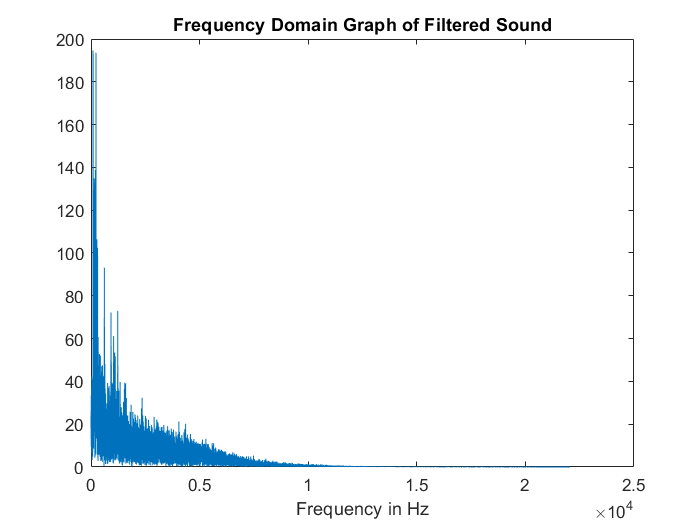

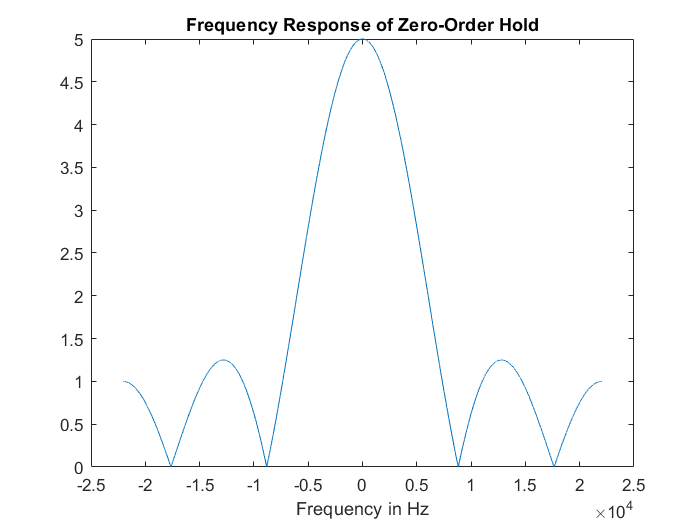

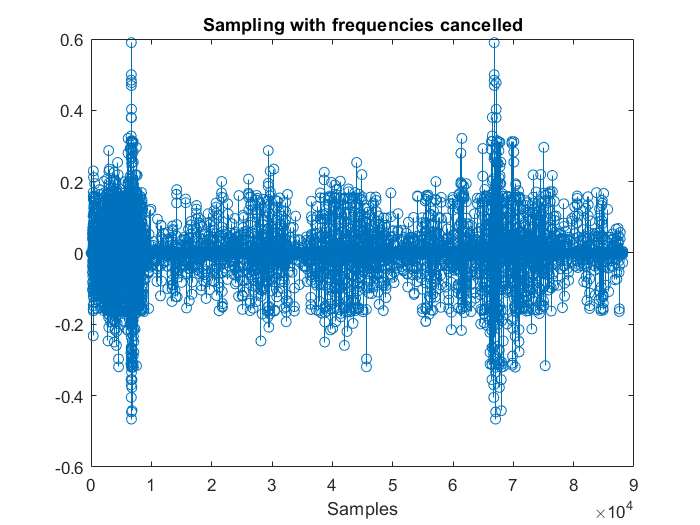

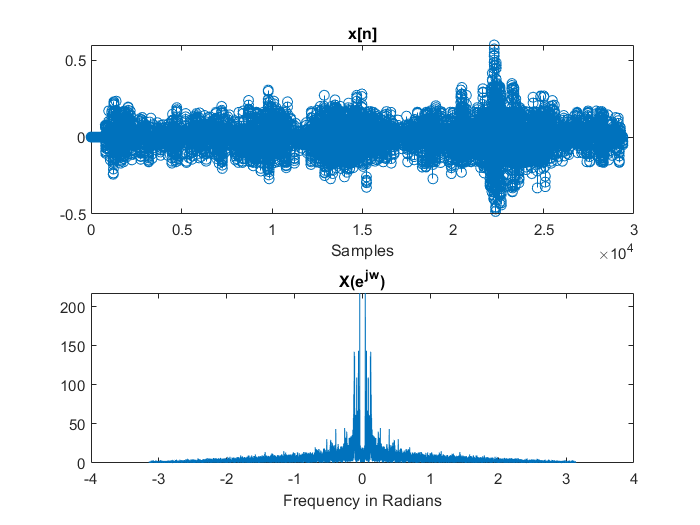

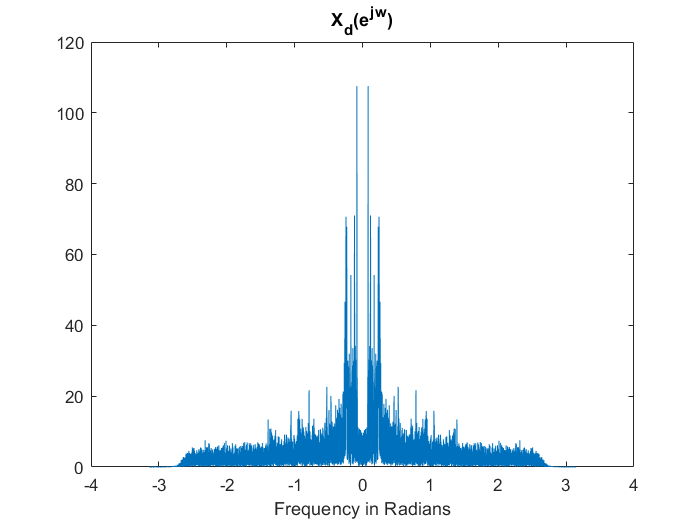

[n, Fsn] = audioread('noise.wav');
n = n(1:88200/6);
for t = 1:length(n)
    s(t) = n(t) + xd(t);
    drawnow;    %USing this method and command as simply adding the two was a burden on memory
end

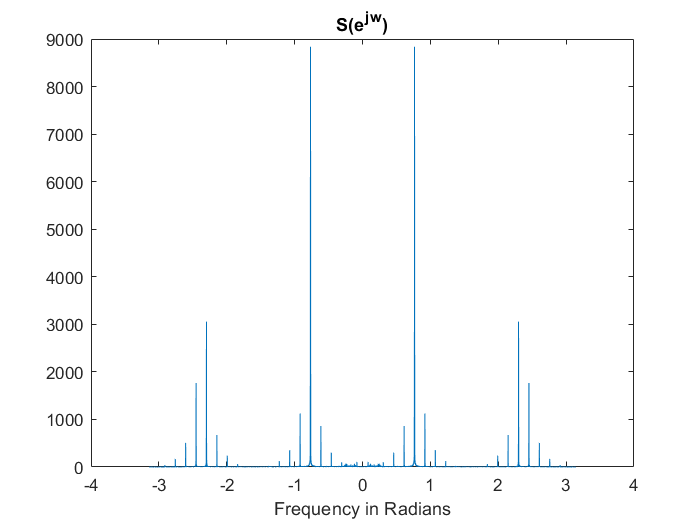

S = fftshift(fft(s, length(x)));
figure(8);
plot(f, abs(S));
title('S(e^j^w)');
xlabel('Frequency in Radians');

disp('After adding the noise to the signal, we see various impulses of the noise at various frequencies.');

After adding the noise to the signal, we see various impulses of the noise at various frequencies.


**Task 7**

Filter out the noise from the frequency spectrum.

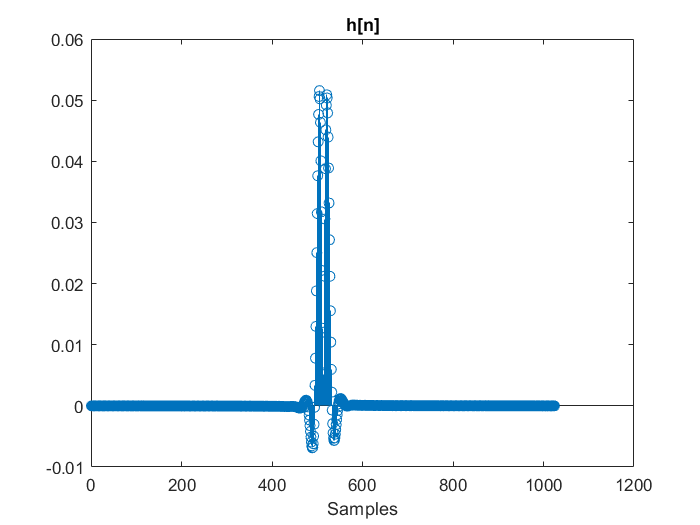

[b, a] = butter(3, 0.25/pi, 'low');
[W, x] = freqz(b, a);
W = W.';
Wd = fliplr(W);
W = [Wd W];
h = fftshift(ifft(ifftshift(W)));
figure(9);
stem(real(h));
title('h[n]');
xlabel('Samples');

disp('The impulse response of the filter is a sinc function');

The impulse response of the filter is a sinc function


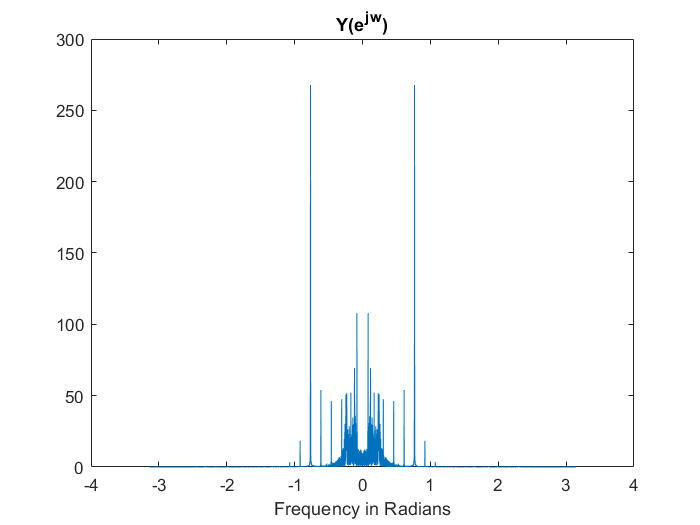

y = filter(b, a, s);
Y = fftshift(fft(y, 29400));
figure(10);
plot(f, abs(Y));
title('Y(e^j^w)');
xlabel('Frequency in Radians');

disp('Now we have filtered out the frequency impulses that came from the noise, the graph now resembles Xd(e^j^w) more.');

Now we have filtered out the frequency impulses that came from the noise, the graph now resembles Xd(e^j^w) more.


**Task 8**

Upsample the resultant signal and show the frequency response.

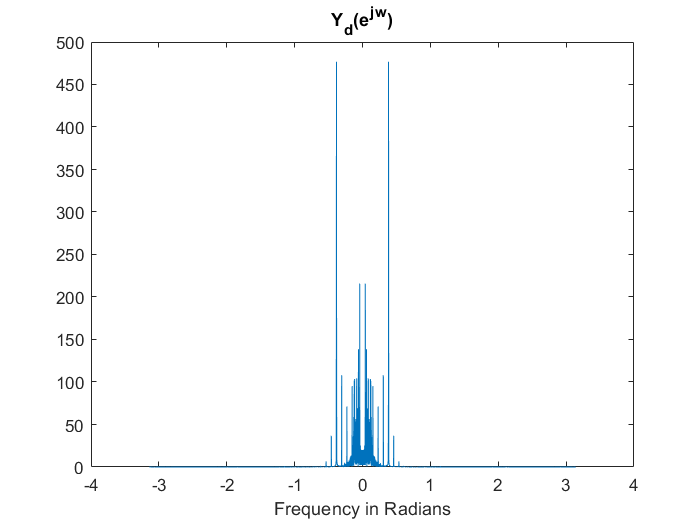

yd = interp(y, 2);  %Upsampling the signal by 2 using interpolation
Yd = fftshift(fft(yd));
figure(11);
plot(f, abs(Yd));
title('Y_d(e^j^w)');
xlabel('Frequency in Radians');

disp('When we compare this to the graph of Y(e^j^w), we see that it has contracted in the frequency axis, just as discussed in the lectures');

When we compare this to the graph of Y(e^j^w), we see that it has contracted in the frequency axis, just as discussed in the lectures


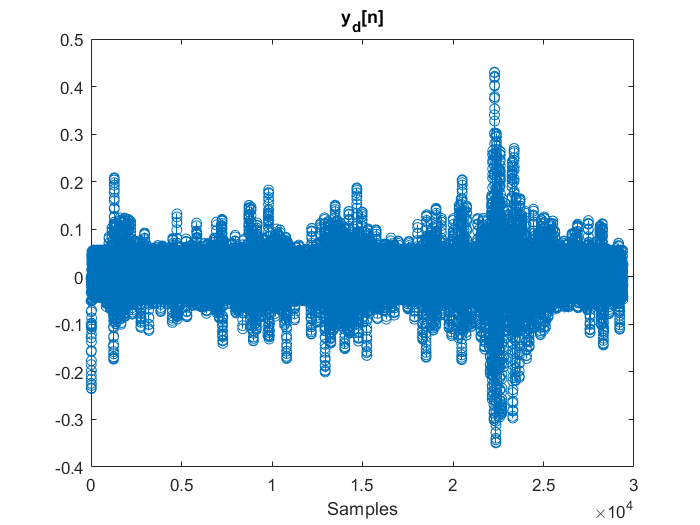

figure(12);
stem(yd);
title('y_d[n]');
xlabel('Samples');